# Computation on the numerical limits

Assume functions : $f_1 \left(x\right)=\text{ }\frac{1−cos\left(2x\right)}{2x\text{ }sin\left(x\right)}$ and $f_2 \left(x\right)=\text{ }\frac{sin\left(x\right)}{x}$  

we know their limitations : $\lim_{x\to 0} f_1 \left(x\right)=\text{ }\lim_{x\to 0} \frac{1−cos\left(2x\right)}{2x\text{ }sin\left(x\right)}=1$,  $\lim_{x\to 0} f_2 \left(x\right)=\text{ }\lim_{x\to 0} \frac{sin\left(x\right)}{x}=1$

Now we want to compute their numerical limit values in MATLAB

How to program to compute them?

k = logspace(0, 14, 15);     % Produce the array [1, 10, 100, 1000, ... 10^14]
x = k * eps;
f1 = (1 - cos(2.*x))./(2*x.*sin(x));
f2 = sin(x)./x;

format short e
disp([blanks(7), 'x', blanks(11), 'f1', blanks(11), 'f2']);    % Display the arguments and functions name

       x           f1           f2


disp([x', f1', f2'])        % Display the arguments and functions list

   2.2204e-16            0   1.0000e+00
   2.2204e-15            0   1.0000e+00
   2.2204e-14            0   1.0000e+00
   2.2204e-13            0   1.0000e+00
   2.2204e-12            0   1.0000e+00
   2.2204e-11            0   1.0000e+00
   2.2204e-10            0   1.0000e+00
   2.2204e-09            0   1.0000e+00
   2.2204e-08   1.0133e+00   1.0000e+00
   2.2204e-07   9.9980e-01   1.0000e+00
   2.2204e-06   1.0000e+00   1.0000e+00
   2.2204e-05   1.0000e+00   1.0000e+00
   2.2204e-04   1.0000e+00   1.0000e+00
   2.2204e-03   1.0000e+00   1.0000e+00
   2.2204e-02   9.9992e-01   9.9992e-01



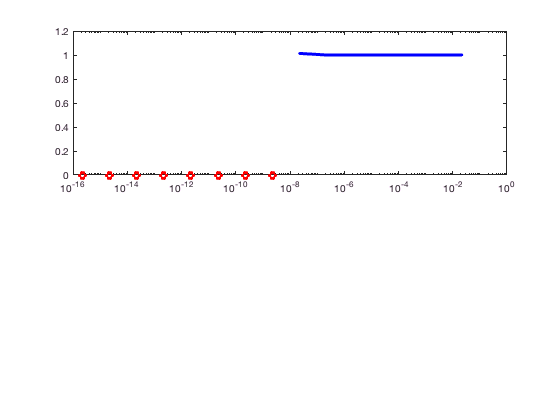

clf

n1 = sum(f1 < 10^(-10));    

subplot(2, 1, 1);
semilogx(x(1:n1), f1(1:n1), 'ro', 'LineWidth', 3)                % Plot the error points
hold on
semilogx(x(n1 + 1:end), f1(n1 + 1:end), 'b.-', 'LineWidth', 3)    % Plot the correct function graph.
hold off